% when executing a section code always make sure you are in the correct
% directory that the code is trying to execute

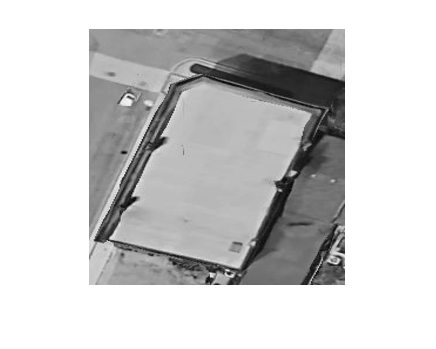

Error using rgb2gray>parse_inputs (line 79)
MAP must be a m x 3 array. Use im2gray for RGB and grayscale images.

Error in rgb2gray (line 51)
isRGB = parse_inputs(X);

OutputFolder = 'D:\All\phd research\PAPER\paper 2\matlab_deep learning\wall_segmentation\data\traingray';  % Set as needed [EDITED]
dinfo = dir('*.png');% image extension
for K = 1 : length(dinfo)
  thisimage = dinfo(K).name;
  Img   = imread(thisimage);
  Y     = imshow(Img);
  Gray  = rgb2gray(Img);
  
  imwrite(Gray, fullfile(OutputFolder, thisimage));  % [EDITED]
end

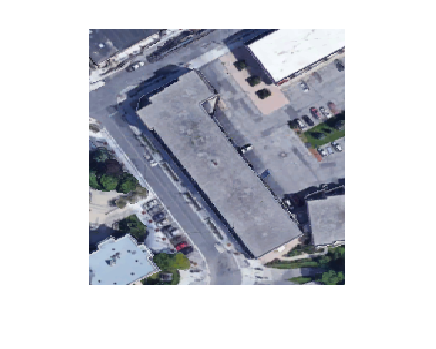

OutputFolder = 'D:\All\phd research\PAPER\paper 2\matlab_deep learning\wall_segmentation\data\valimggray';  % Set as needed [EDITED]
dinfo = dir('*.png');% image extension
for K = 1 : length(dinfo)
  thisimage = dinfo(K).name;
  Img   = imread(thisimage);
  Y     = imshow(Img);
  Gray  = rgb2gray(Img);
  
  imwrite(Gray, fullfile(OutputFolder, thisimage));  % [EDITED]
end

dataFolder  = fullfile('data');

imageDir = fullfile(dataFolder,'traingray');
labelDir = fullfile(dataFolder,'masks');

numObservations = 4;
trainImages = repelem({imageDir},numObservations,1);
trainLabels = repelem({labelDir},numObservations,1);

classNames = ["building","background"];
labelIDs   = [255 0];
imds = imageDatastore(trainImages);
pxds = pixelLabelDatastore(trainLabels,classNames,labelIDs);

trainingData = combine(imds,pxds);

data = read(trainingData);
I = data{1};
C = data{2};

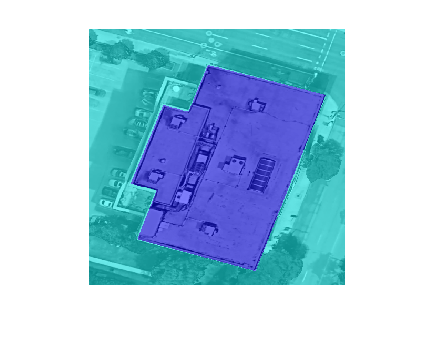

B = labeloverlay(I,C);
imshow(B)

augmentedTrainingData = transform(trainingData,@jitterImageColorAndWarp);

data = readall(augmentedTrainingData);

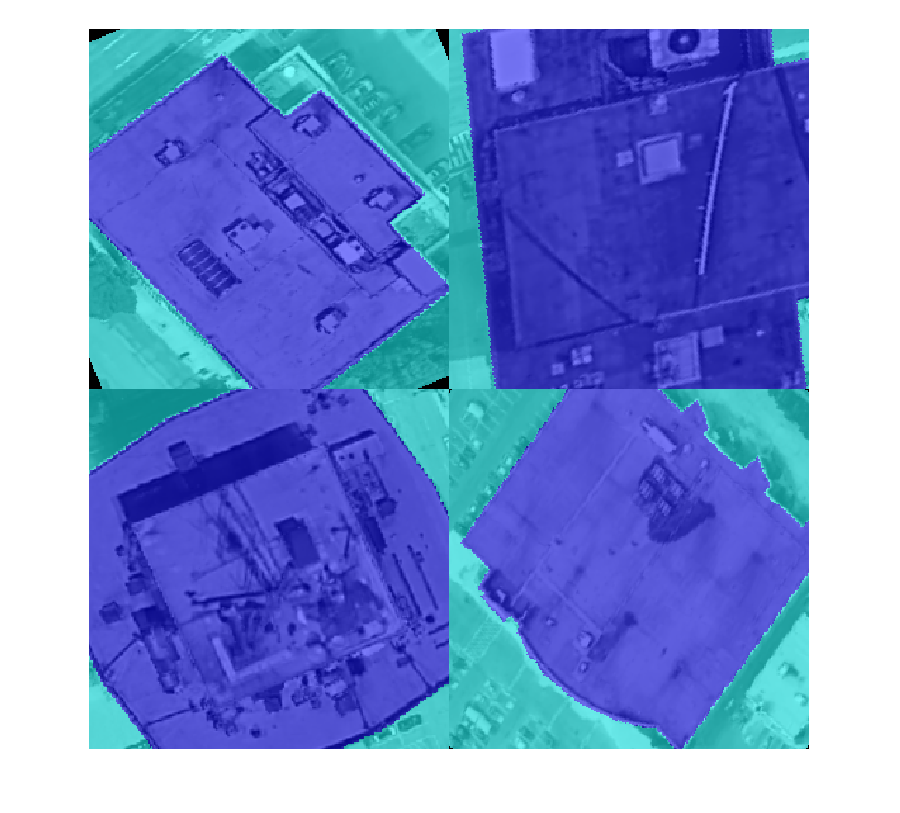

rgb = cell(numObservations,1);
for k = 1:numObservations
    I = data{k,1};
    C = data{k,2};
    rgb{k} = labeloverlay(I,C);
end
montage(rgb)

imageSize = [256 256];
numClasses = 2;
lgraph = unetLayers(imageSize, numClasses)

lgraph =   LayerGraph with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


lgraph.Layers

ans =   58×1 Layer array with layers:

     1   'ImageInputLayer'                      Image Input                  256×256×1 images with 'zerocenter' normalization
     2   'Encoder-Stage-1-Conv-1'               Convolution                  64 3×3 convolutions with stride [1  1] and padding 'same'
     3   'Encoder-Stage-1-ReLU-1'               ReLU                         ReLU
     4   'Encoder-Stage-1-Conv-2'               Convolution                  64 3×3 convolutions with stride [1  1] and padding 'same'
     5   'Encoder-Stage-1-ReLU-2'               ReLU                         ReLU
     6   'Encoder-Stage-1-MaxPool'              Max Pooling                  2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'Encoder-Stage-2-Conv-1'               Convolution                  128 3×3 convolutions with stride [1  1] and padding 'same'
     8   'Encoder-Stage-2-ReLU-1'               ReL

targetSize= [144 144];
preprocessedTrainingData = transform(augmentedTrainingData,...
    @(data)centerCropImageAndLabel(data,targetSize));

data=readall(preprocessedTrainingData);

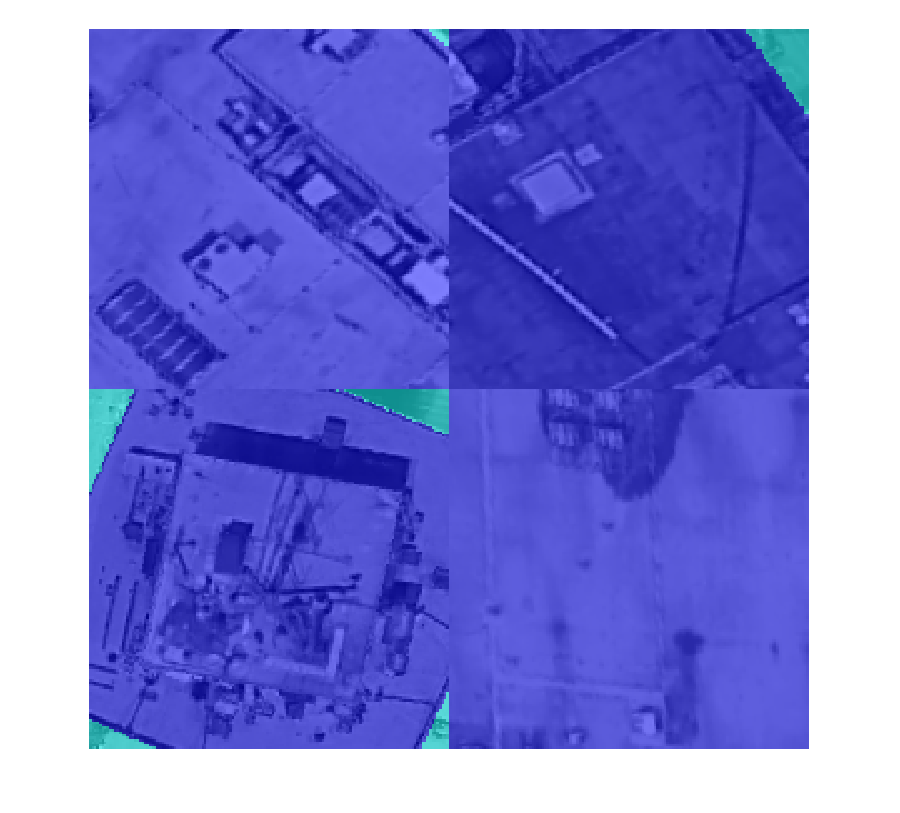

rgb = cell(numObservations,1);
for k = 1:numObservations
    I = data{k,1};
    C = data{k,2};
    rgb{k} = labeloverlay(I,C);
end
montage(rgb)

alldata=combine(trainingData,augmentedTrainingData);

val_img="data\valimggray";
val_mask="data\val_masks";
valimgids=imageDatastore(val_img);

valclassNames = ["building","background"];
vallabelIDs   = [255 0];
valpxds = pixelLabelDatastore(val_mask,valclassNames,vallabelIDs);
valData = combine(valimgids,valpxds);

checkpointPath = pwd;
options = trainingOptions('adam', ...
    'InitialLearnRate',1e-3, ...
    'MaxEpochs',30, ...
    'Shuffle','every-epoch', ...
    'MiniBatchSize',4, ...
    'VerboseFrequency',50, ...
    'Plots','training-progress', ...
    'ValidationData',valData, ...
    'CheckpointPath',checkpointPath);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |       27.64% |       70.71% |      10.8080 |       4.6700 |          0.0010 |
|       1 |          50 |       00:00:58 |       70.69% |       68.79% |       0.9249 |       1.1125 |          0.0010 |
|       1 |         100 |       00:01:42 |       67.30% |       69.64% |       0.8671 |       0.6689 |          0.0010 |
|       1 |         150 |       00:02:26 |       79.78% |       69.29% |       0.4709 |   

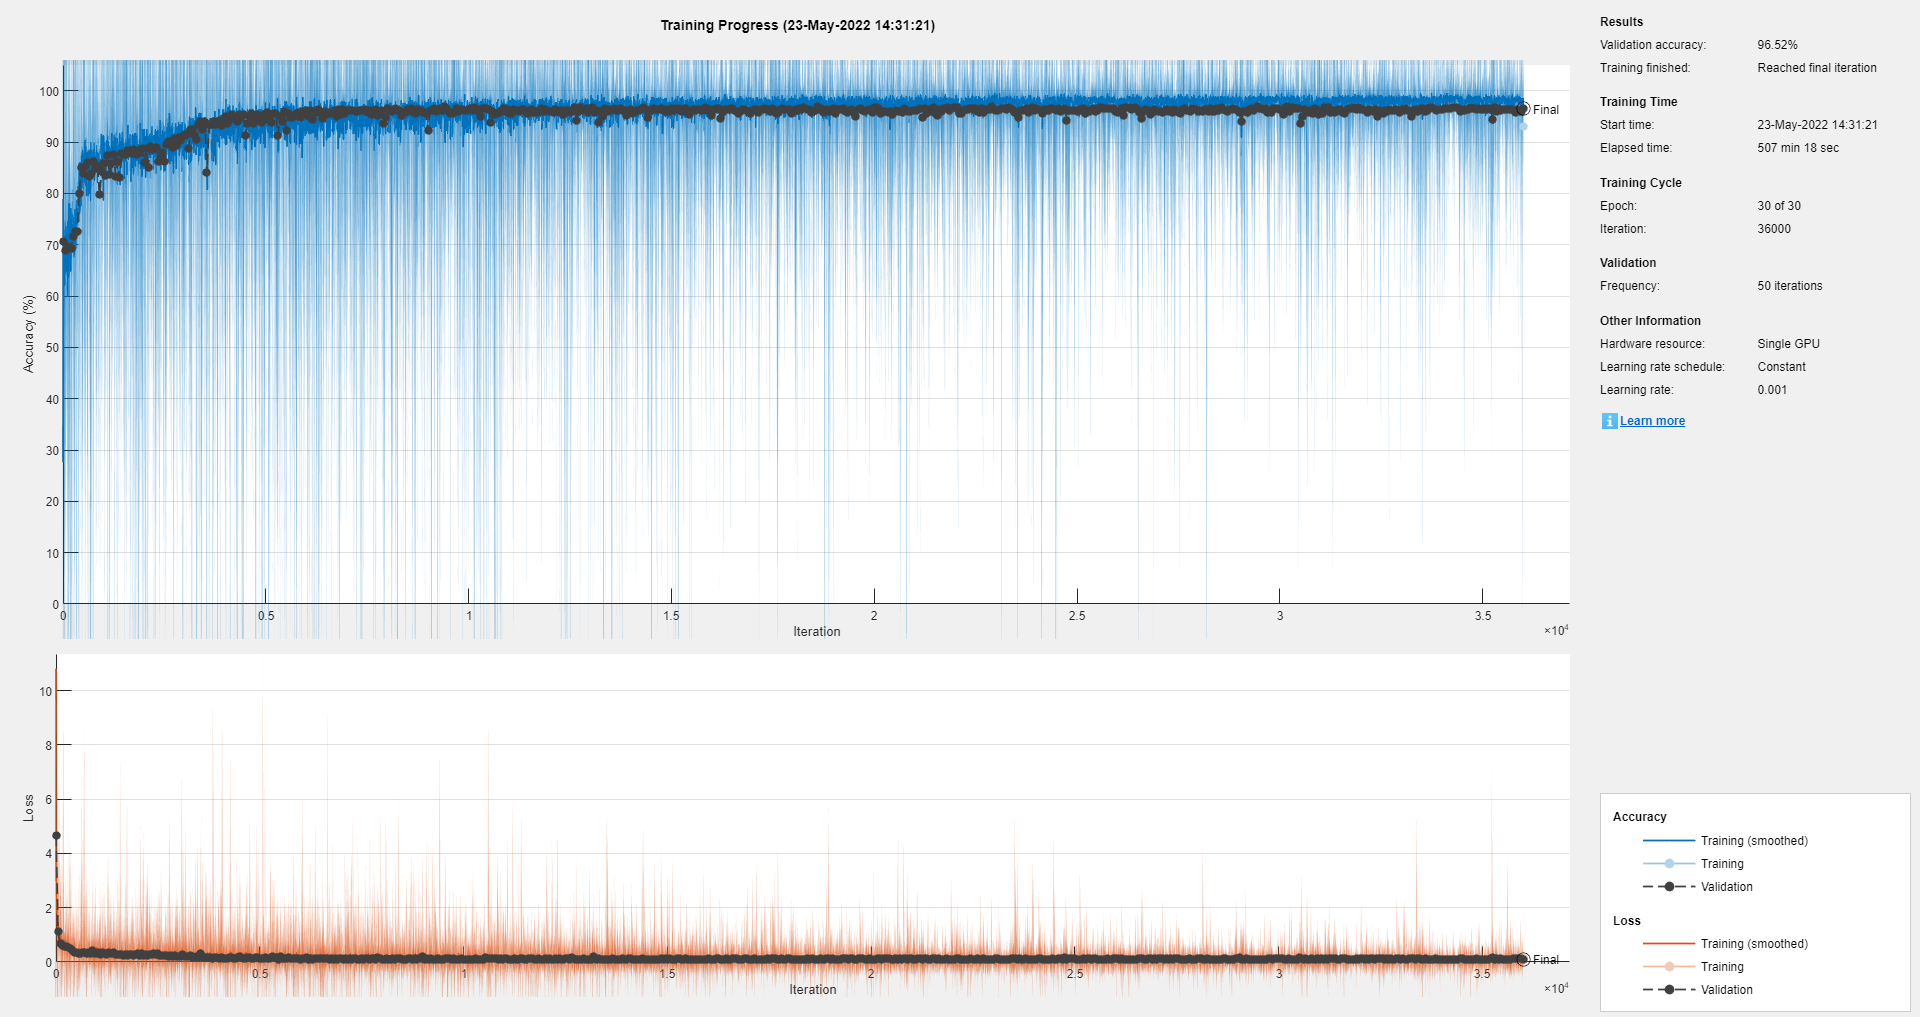

net =   DAGNetwork with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


net = trainNetwork(alldata,lgraph,options)

alldata9652=net

alldata9652 =   DAGNetwork with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


save alldata9652

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |       62.85% |       29.29% |       5.4162 |      11.2722 |          0.0010 |
|       1 |          50 |       00:00:47 |       58.24% |       64.99% |       1.2419 |       1.1022 |          0.0010 |
|       1 |         100 |       00:01:27 |       72.95% |       69.29% |       0.6205 |       0.8174 |          0.0010 |
|       1 |         150 |       00:02:07 |       68.99% |       67.94% |       0.7018 |   

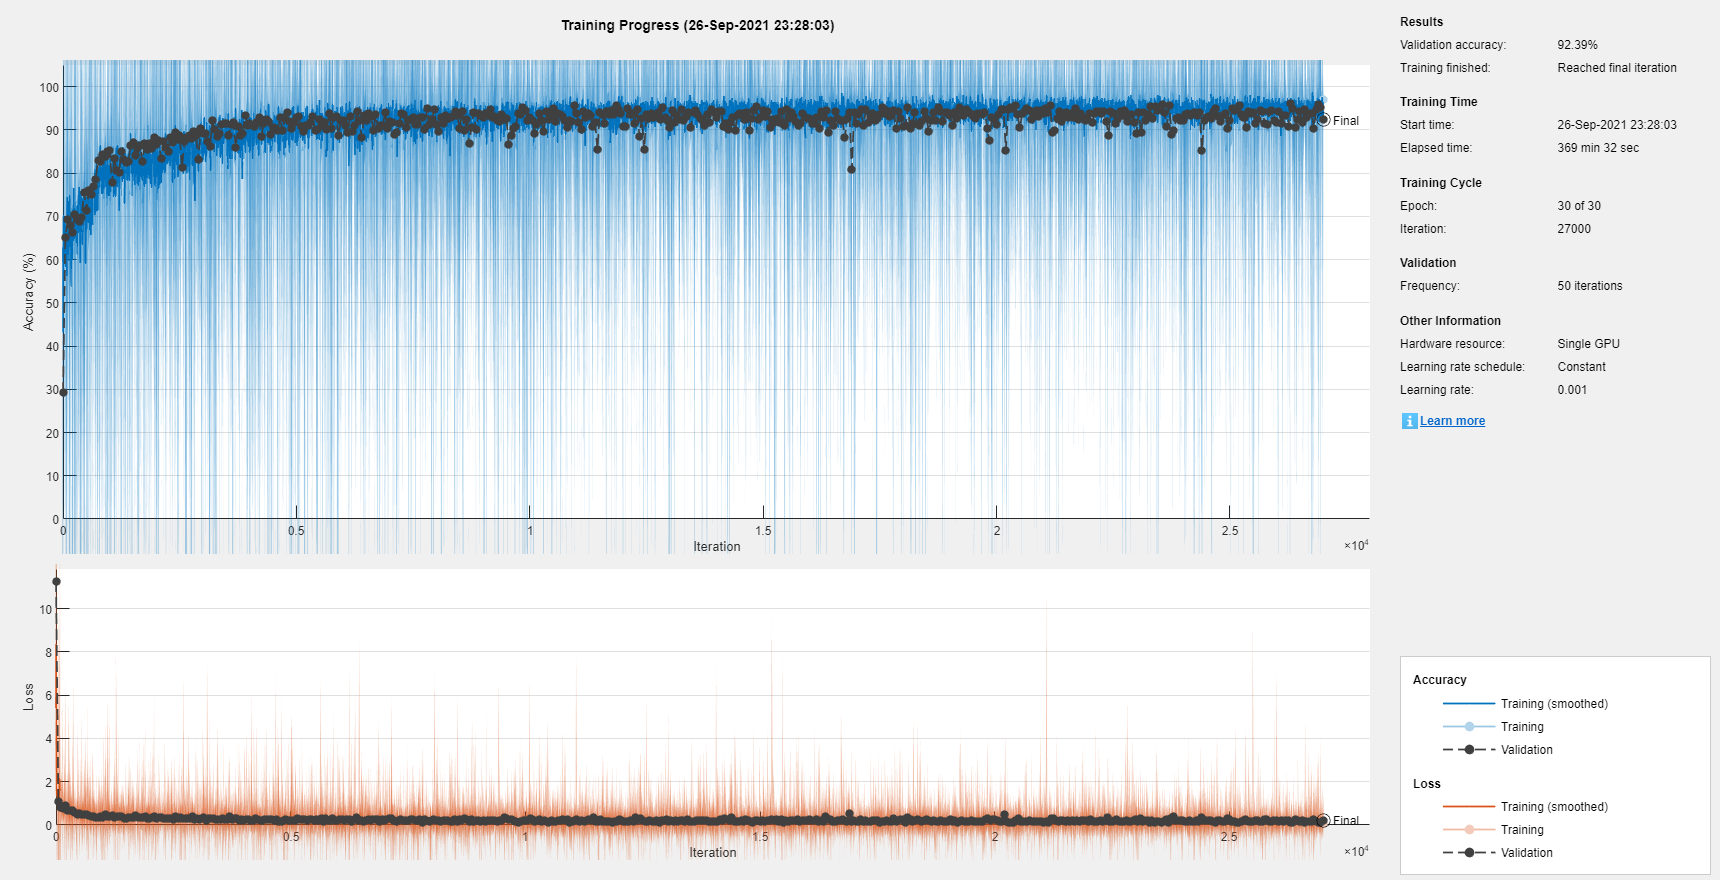

netaugment =   DAGNetwork with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


netaugment = trainNetwork(augmentedTrainingData,lgraph,options)

netaugment_30e_3lr_adam=netaugment

netaugment_30e_3lr_adam =   DAGNetwork with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


save netaugment_30e_3lr_adam  

netaugmented2 = trainNetwork(preprocessedTrainingData,lgraph,options)

Error using trainNetwork (line 184)
The validation images are of size 256×256×1 but the input layer expects images of size 144×144×1.

net.Layers

ans =   58×1 Layer array with layers:

     1   'ImageInputLayer'                      Image Input                  256×256×1 images with 'zerocenter' normalization
     2   'Encoder-Stage-1-Conv-1'               Convolution                  64 3×3×1 convolutions with stride [1  1] and padding 'same'
     3   'Encoder-Stage-1-ReLU-1'               ReLU                         ReLU
     4   'Encoder-Stage-1-Conv-2'               Convolution                  64 3×3×64 convolutions with stride [1  1] and padding 'same'
     5   'Encoder-Stage-1-ReLU-2'               ReLU                         ReLU
     6   'Encoder-Stage-1-MaxPool'              Max Pooling                  2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'Encoder-Stage-2-Conv-1'               Convolution                  128 3×3×64 convolutions with stride [1  1] and padding 'same'
     8   'Encoder-Stage-2-ReLU-1'          

a=dir(["data\traingray\*.png"])

a = 900×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


out=size(a,1)

out = 900

load('net_checkpoint__2700__2021_09_20__22_17_01.mat','net')

checkpointPath = pwd;
options = trainingOptions('adam', ...
    'InitialLearnRate',1e-3, ...
    'MaxEpochs',1, ...
    'Shuffle','every-epoch', ...
    'MiniBatchSize',4, ...
    'VerboseFrequency',1, ...
    'Plots','training-progress', ...
    'ValidationData',valData, ...
    'CheckpointPath',checkpointPath);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |       96.50% |       92.94% |       0.0909 |       0.2275 |          0.0010 |
|       1 |           2 |       00:00:09 |       93.38% |              |       0.1983 |              |          0.0010 |
|       1 |           3 |       00:00:09 |       90.15% |              |       0.3242 |              |          0.0010 |
|       1 |           4 |       00:00:10 |       92.28% |              |       0.2899 |   

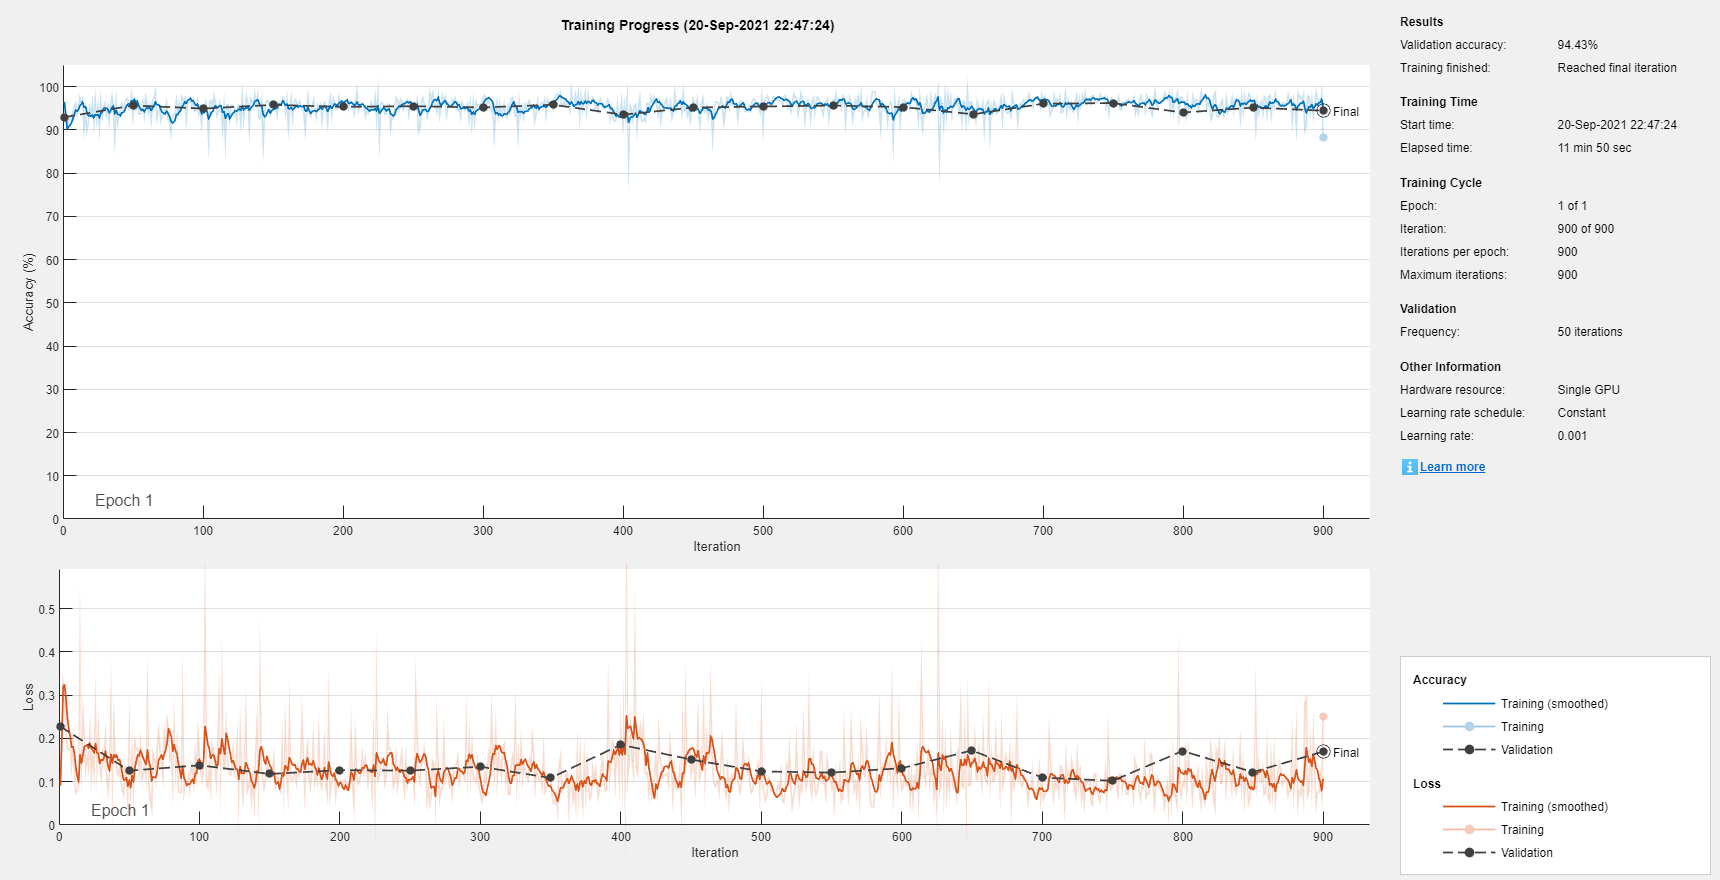

net1 =   DAGNetwork with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


net1 = trainNetwork(trainingData,layerGraph(net),options)

Burbax=net;
save Burbax

testImage=imread('18_gs.jpg');



testImage=imresize(testImage,[256 256])

testImage = 256×256 uint8 matrix
   159   158   157   157   156   155   155   155   155   156   156   156   156   155   155   154   154   154   154   153   153   152   151   151   151   150   149   149   148   146   144   141   139   137   136   135   135   136   137   136   134   134   134   135   137   139   141   146   146   147
   157   157   156   155   155   155   155   155   155   156   156   156   156   155   155   154   154   154   154   153   153   152   152   152   151   150   149   149   148   148   148   146   145   143   142   140   139   139   138   138   136   134   133   131   131   131   131   142   142   143
   154   155   154   154   155   155   155   155   154   155   155   155   155   155   155   155   155   155   155   154   154   153   152   151   151   151   150   150   148   148   150   150   150   149   147   145   145   142   140   140   140   140   139   137   135   133   132   136   136   137
   151   152   153   153   154   155   155   154   154   155   1

imwrite(testImage,'wow.png')
testImage=imread('wow.PNG');
imshow(testImage)

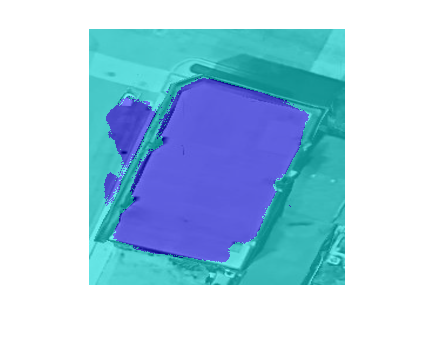

C=semanticseg(testImage,net);

B=labeloverlay(testImage,C);
imshow(B)

testImage=imread('predictbuilding.PNG');



testImage=imresize(testImage,[256 256])

testImage = 256×256×3 uint8 array
testImage(:,:,1) =

    55    45    66    99   100   127    98    50    91    74    79    84    65    50   120   146   184   172   115    97   104    99   178   175   120    93    53    63    56    56    70    60    75   175   158   197   193   146   135   138    78    95   129   155   110   103   110   111   152   148   163   106    73   122   156   162   129    81    67    61    32    35    46    30    36    61    60    81    74    51    48    62   100   116   109    68    40    49    61    53    59   117   183   175   107    63   110   123   136   146   130    99    94    83    76    70    67    76   157   161   156   163   131   129   161   178   164   163   157   150   172   145   104    61    79   167   182    94   140   164   180   175    96   103    60   120   123    95    65   106   161   177   194   147   131    86    66    60    88   162   188   183   179   176   175   156    82    66    59   154   202   158   144   145   103    59    96   1

imwrite(testImage,'wow1.png')
testImage=imread('wow1.PNG');
imshow(testImage)
C=semanticseg(testImage,net);
B=labeloverlay(testImage,C);
imshow(B)